Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:17 |       28.12% |       46.29% |       1.5023 |       1.0748 |          0.0010 |
|       1 |          50 |       00:00:40 |      100.00% |       99.91% |       0.0374 |       0.0266 |          0.0010 |
|       1 |         100 |       00:01:03 |      100.00% |      100.00% |       0.0072 |       0.0076 |          0.0010 |
|       1 |         150 |       00:01:27 |      100.00% |      100.00% |       0.0032 |   

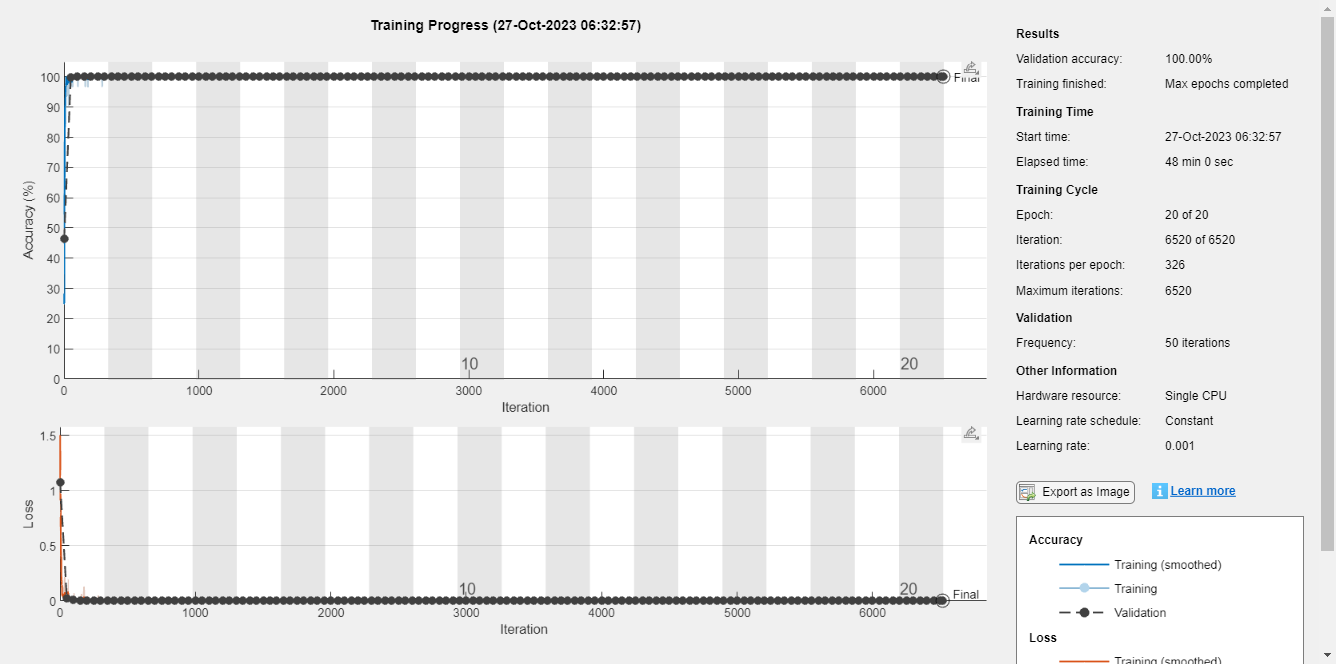

clear all;
close all;
clc;

% Define the path to your dataset
dataDir = 'C:\IIT Panta__MTech_2023\01. Semester 1\06. Digital Image processing\Rose'; % Change this path to your dataset directory

% Create an imageDatastore for your dataset and specify the desired output size
imds = imageDatastore(dataDir, ...
    'IncludeSubfolders', true, 'LabelSource', 'foldernames', 'ReadFcn', @(filename) imresize(imread(filename), [64, 64]));

% Define the CNN architecture
layers = [
    imageInputLayer([64 64 3])
    
    convolution2dLayer(3, 16, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2, 'Stride', 2)
    
    convolution2dLayer(3, 32, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2, 'Stride', 2)
    
    fullyConnectedLayer(3) % 2 classes: Blackspot and Rose Mosaic
    softmaxLayer
    classificationLayer
];

% Split the dataset into training and validation sets
[imdsTrain, imdsValidation] = splitEachLabel(imds, 0.7, 'random');

% Define training options
options = trainingOptions('sgdm', ...
    'MaxEpochs', 20, ...
    'MiniBatchSize', 32, ...
    'InitialLearnRate', 0.001, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', imdsValidation, ...
    'ValidationFrequency', 50, ...
    'Verbose', true, ...
    'Plots', 'training-progress');

% Train the CNN
net = trainNetwork(imdsTrain, layers, options);



% Perform predictions on validation data
YPred = classify(net, imdsValidation);
YValidation = imdsValidation.Labels;

% Calculate classification accuracy
accuracy = sum(YPred == YValidation) / numel(YValidation);

% Display the accuracy
disp(['Validation Accuracy: ', num2str(accuracy * 100), '%']);

Validation Accuracy: 100%



% Use uigetfile to interactively select the new image
[filename, pathname] = uigetfile({'image.jpg', 'JPEG Files (*.jpg)'}, 'C:\IIT Panta__MTech_2023\New folder');
if isequal(filename,0)
    disp('User canceled the operation');
else
    % Combine the selected path and filename
    fullFilePath = fullfile(pathname, filename);

    % Load the selected image and classify it
    newImage = imread(fullFilePath);

    % Preprocess and resize the new image to match the input size of the trained model
    newImage = imresize(newImage, [64, 64]);

    % Use the trained model to classify the new image
    predictedClass = classify(net, newImage);

    % Display the predicted class
    disp(['Predicted Class: ', char(predictedClass)]);
end

Predicted Class: Rose_sawfly_Rose_slug





if predictedClass == 'Rose Mosaic'
    display('There is no cure or treatment in landscapes for eliminating the viruses that cause rose mosaic disease');
    elseif predictedClass == 'Blackspot'
    display('Some gardeners have reported varying degrees of success using sprays made of milk, vinegar, or hydrogen peroxide diluted with water');
else
    display('Some')
end

Some
